# Block Diagram Reduction 

## Blocks 

sys1 = tf(10,[1 16])

sys1 =
 
    10
  ------
  s + 16
 
Continuous-time transfer function.
Model Properties


sys2 = tf([1 4],[1 4 25])

sys2 =
 
      s + 4
  --------------
  s^2 + 4 s + 25
 
Continuous-time transfer function.
Model Properties


## Series 

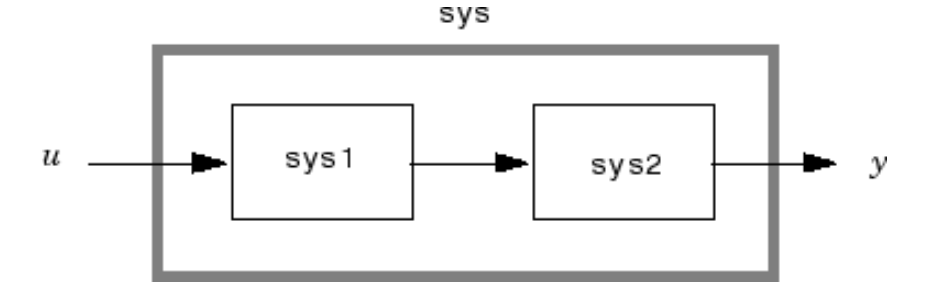

sys_s = series(sys1,sys2)

sys_s =
 
          10 s + 40
  -------------------------
  s^3 + 20 s^2 + 89 s + 400
 
Continuous-time transfer function.
Model Properties


## Parallel 

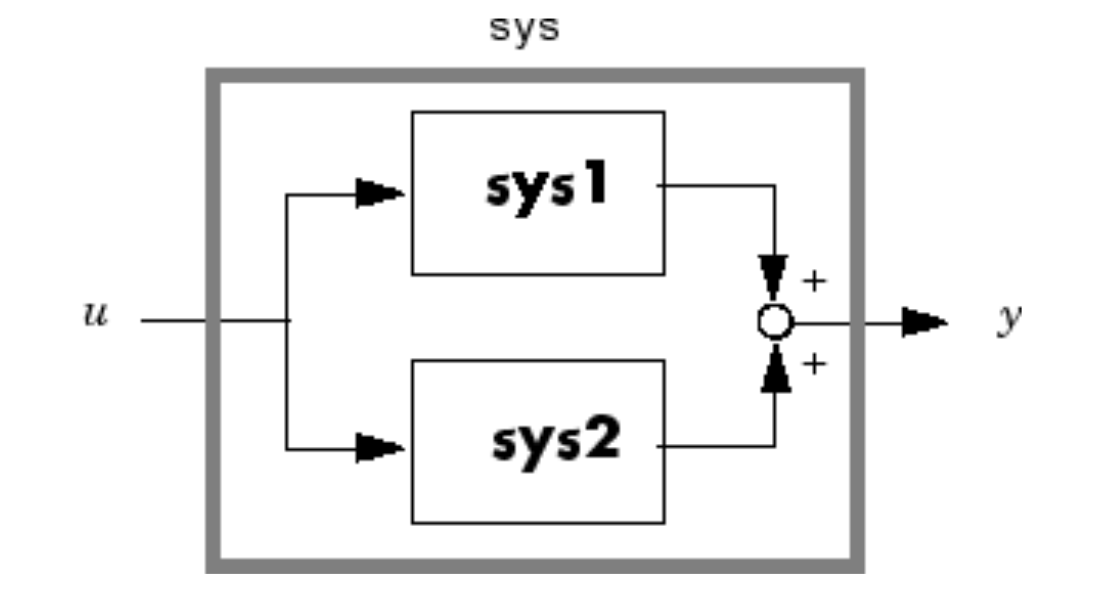

sys_p = parallel(sys1,sys2)

sys_p =
 
     11 s^2 + 60 s + 314
  -------------------------
  s^3 + 20 s^2 + 89 s + 400
 
Continuous-time transfer function.
Model Properties


## Feedback 

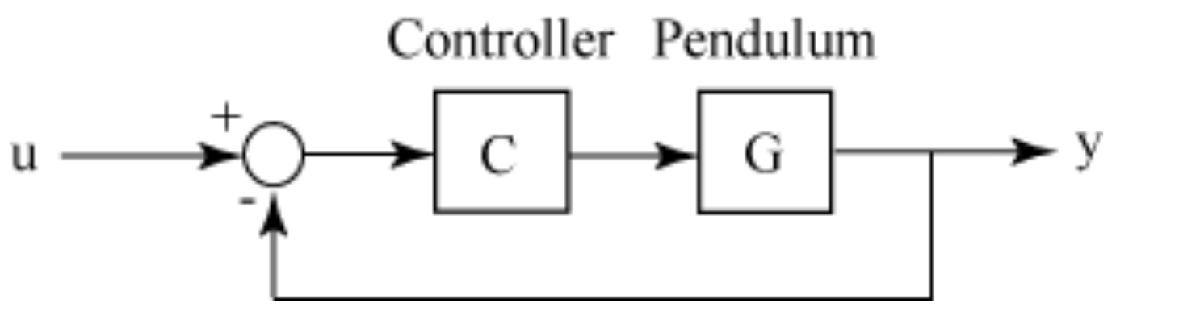

Documentation - [feedback](https://in.mathworks.com/help/control/ref/inputoutputmodel.feedback.html)

s = tf('s');
C = pid(4,0.1,0.4)

C =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 4, Ki = 0.1, Kd = 0.4
 
Continuous-time PID controller in parallel form.
Model Properties


G = P_motor

G =
 
             0.01
  ---------------------------
  0.005 s^2 + 0.06 s + 0.1001
 
Continuous-time transfer function.
Model Properties


closed_tf = feedback(G*C,1)

closed_tf =
 
         0.004 s^2 + 0.04 s + 0.001
  ----------------------------------------
  0.005 s^3 + 0.064 s^2 + 0.1401 s + 0.001
 
Continuous-time transfer function.
Model Properties
